# Port-Hamiltonian Balancing

## Introduction

Different balancing methods for port-Hamiltonian systems exist in the literature, see, e.g. [1], [2]. Here the method from [1] is presented. This method is advantageous in that for some cases $\mathcal{H}_\infty$ error bounds hold. The method balances the system with respect to the observability and a modified controllability Gramian.

### The idea

The idea of balancing-based methods is to look for a transformation that brings the system in a balanced representation where states that are less relevant to the transfer behavior can be identified and subsequently truncated. Balancing for pH systems use the observability Gramian and a modified controllability Gramian. For pH systems it can be verified that the modified controllability Gramian is the inverse of the system matrix $Q$.

### Pseudo-Code

## Toolbox Implementation

The MORpH toolbox provides an implementation of port-Hamiltonian Balancing in the function *balPH*.

For more information, refer to the documentation:

help balPH

  balPH - obtains a reduced order port-Hamiltonian system by
          balancing w.r.t. modified Gramians.
 
  Syntax:
    sysr = balPH(sys)
    sysr = balPH(sys, r)
    sysr = balPH(sys, Opts)
    sysr = balPH(sys, r, Opts)
 
  Description:
        sysr = balPH(sys, r, Opts) returns a reduced PH system with
        given order r by balanced truncation with a modified controllability
        Lyapunov equation [1].
 
        If r equals the system order, the phs-object sysr is the balanced
        realization.
 
        Used options, modified Hankel singular values and projection matrix
        Wr are stored in the phs object sysr.
 
        If a reduced order is passed to the function the reduced system
        will be this size. In this case Opts.truncTol is ignored. If no reduced
        order is provided the system is truncated according to Opts.truncTol
        if the value is grea

## Example

The example considered here is a SISO Ladder Network with an architecture as shown below:  

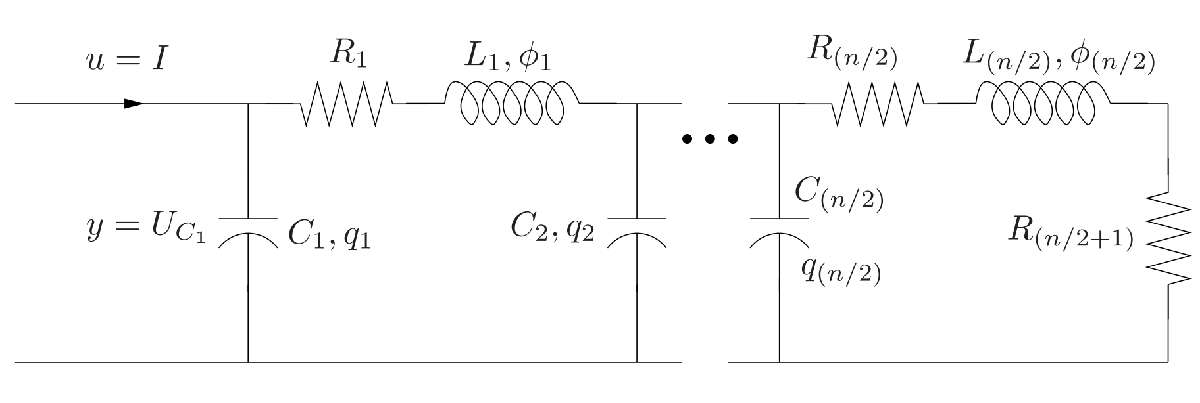

Image source: [2]

We consider a model with dimension $n = 100$, i.e. 50 inductances ($L_i = 0.2\text{H}$), 50 capacitors ($C_i = 0.2\text{F}$) and 51 resistances ($R_i=1\Omega$).

sys = setup_LadderNetworkSystem(100,.2,.2,1)

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×1 double]
               E: [100×100 double]
               P: [100×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


*balPH* in its simplest form is called by providing the system to reduce (user input required in command window): 

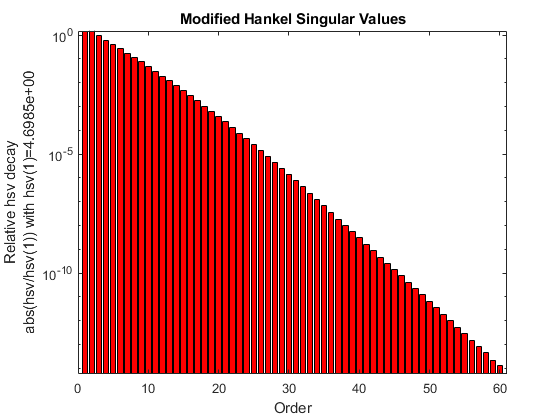

sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @balPH
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


sysr = balPH(sys)

norm(ss(sys) - ss(sysr))

ans = 0.0435

### Options

*balPH* provides some (nested) options. The levels of options are:

- Top level (*balPH*): e.g. truncation tolerance

- Second level (*mess_lradi*): e.g. number of adi iterations

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help phs

  phs (class) - class and methods for handling port-Hamiltonian systems
 
  Syntax:
    sys = phs(J, R, Q, G)
    sys = phs(J, R, Q, G, E)
    sys = phs(J, R, Q, G, Opts)
    sys = phs(J, R, Q, G, E, Opts)
    sys = phs(J, R, Q, G, E, P, S, N)
    sys = phs(J, R, Q, G, E, P, S, N, Opts)
 
  Description:
        sys = phs(J, R, Q, G) returns a phs-object representing the
        port-Hamiltonian system sys defined by
            dx/dt = (J - R)*Q*x(t) + G*u(t)
                y = G'*Q*x
             H(x) = 0.5*x'*Q*x      (Hamiltonian)
                f = -dx/dt     (flow)
                e = grad_x(H)  (effort)        [1,2]
 
        sys = phs(J, R, Q, G, E) returns a phs-object representing the
        port-Hamiltonian system sys defined by
            E*dx/dt = (J - R)*Q*x(t) + G*u(t)
                  y = G'*Q*x
               H(x) = 0.5*x'*E'*Q*x   (Hamiltonian)
                  f = -dx/dt     (fl

To provide these options, use nested structs. As an example, the following code changes the Lyapunov equation solver:

Opts = struct();
Opts.lyap = 'lyapchol';     % Function to solve Lyapunov equation
Opts

Opts = struct with fields:
    lyap: 'lyapchol'



sysr = balPH(sys,10,Opts)

sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @balPH
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


norm(ss(sys) - ss(sysr))

ans = 0.0435

isPassive(ss(sysr))

ans = logical
   1


### Output

*balPH* provides only the reduced system as output. This phsRed object contains additional information which makes the creation more transparent:

sysr.method         % Method with which the system was created (should be @balPH)

ans = function_handle with value:
    @balPH


sysr.parameters     % Execution parameters (options)         

ans = struct with fields:
          lyap: 'lyapchol'
    mess_lradi: [1×1 struct]
      truncTol: 0
        hsvTol: 1.0000e-15
           phs: [1×1 struct]
    truncation: 'redOrder'
            Wr: [100×10 double]
           hsv: [100×1 double]


## References

[1] T. Breiten, R. Morandin, and P. Schulze. Error bounds for port-Hamiltonian model and controller reduction based on system balancing. Comput. Math. Appl., 2021.

[2] R. V. Polyuga and A. van der Schaft. "Effort- and Flow-Constraint Reduction Methods for Structure Preserving Model Reduction of Port-Hamiltonian Systems." In: Systems Control Lett. 61.3 (2012), pp. 412–421.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)